## **Advanced Audio Signal Processing and Noise Reduction **

### **(Unleashing Sonic Synergy through Harmonic Resonance)**

**Presented to:**

                     Dr. Ahmad Salman

**Presented by:**

•	Wahab Hassan Janjua    (341658)

•	Fahad Arshad                 (331804)

•	M. Hamza Naeem           (335797)

## **Title: Advanced Audio Signal Processing and **

## **Noise Reduction**

**Introduction**

The purpose of this project is to perform various signal processing and analysis techniques on an audio signal. The project aims to explore different aspects of audio signal processing, such as spectral analysis, filtering, noise removal using adaptive filters like least mean squares (LMS) algorithm, voice activity detection (VAD), and volume control through GUI.

**Methodology	**

The project is implemented using MATLAB, a powerful tool for signal processing and analysis. The following steps are involved in the project:

**Reading and Preprocessing the Audio Signal**

The project begins by reading an audio signal from a file (GGG.WAV) using the `audioread` function. The stereo signal is converted to mono by taking the mean of the two channels.

**Spectral Analysis**

The project first displays the sample rate of the signal and then computes and displays the spectrogram of the input audio signal using the `specgram` function. Additionally, the power spectral density of the signal is plotted using the `psd` function.

**Fourier Transform**

The Fourier transform of the audio signal is calculated using the `fft` function. The magnitude spectrum is plotted, showing the frequency components and their amplitudes. The bandwidth of the signal is also visualized using a graph.

**Filter Design and Application**

The project includes the design and application of different types of filters, namely low-pass, high-pass, bandpass, and bandstop filters. The low-pass and high-pass filters are designed using the `fdesign` and `design` functions, and the signals are filtered using the `filter` function. The occupied bandwidth of the filtered signals is plotted.

**Noise Removal**

White noise is added to the original signal using the `awgn` function. An adaptive filter based on the least mean squares (LMS) algorithm is employed to remove the noise. The filtered signal is then displayed using a spectrogram.

**Voice Activity Detection (VAD)**

The short-term energy of the noise-removed signal is calculated, and a threshold is set for voice activity detection. Frames of the signal are analyzed, and a binary result indicating speech or silence is obtained. The original audio signal and the VAD result are plotted.

**Volume Control**

A graphical user interface (GUI) is created to control the volume of the audio signal. A slider is provided to adjust the volume level, and the audio is played back at the desired volume using the `sound` function.

## **Code Explanation:**

% Wahab
clear all; % Remove all variables from the workspace
close all; % Close all figures
clc; % Clear Command Window

clear y Fs; % Here we clear variables y and Fs
% Reading the Audio signal
[y, Fs] = audioread('GGG.WAV');
size(y)

ans =       183296           2


% Convert stereo to mono
y = mean(y, 2);

% Create a figure window
figure;

% Display the sample rate of the signal
Y = ['The Sample rate of the signal is ', num2str(Fs)];
disp(Y);

The Sample rate of the signal is 44100


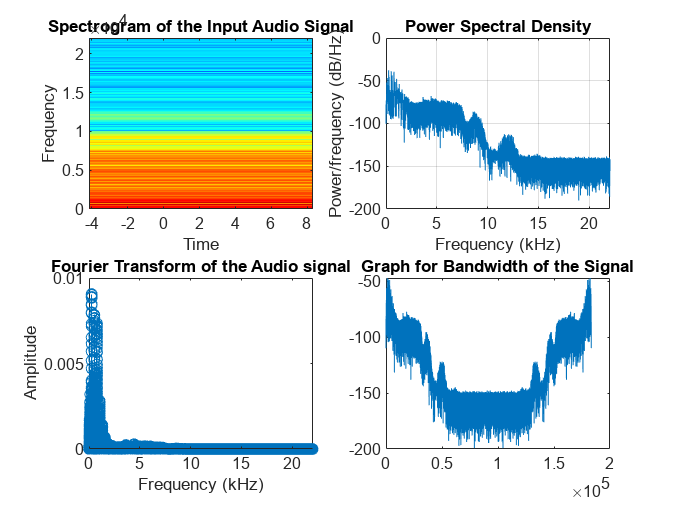


% Spectrogram of the input audio signal
subplot(2, 2, 1);
specgram(y, length(y), Fs);
title('Spectrogram of the Input Audio Signal');

% Plot the power spectral density of the signal
subplot(2, 2, 2);
plot(psd(spectrum.periodogram, y, 'Fs', Fs, 'NFFT', length(y)));
title('Power Spectral Density');

% Calculate the Fourier Transform of the signal
N = length(y);
FFT = fft(y) ./ N;
Fn = Fs/2;
Freq = ((linspace(0, 1, fix(N/2)+1)) .* Fn);
Index = 1 : length(Freq);

% Plot the Fourier Transform of the signal
subplot(2, 2, 3);
stem(Freq./1000, abs(FFT(Index))*2);
title('Fourier Transform of the Audio signal');
xlabel('Frequency (kHz)');
ylabel('Amplitude');

% Plot the bandwidth of the signal
subplot(2, 2, 4);
plot(20*log10(abs(FFT)));
title('Graph for Bandwidth of the Signal');


% Low-pass filter design
d1 = fdesign.lowpass('N,Fc', 10, 1200, 48000);
designmethods(d1);

Design Methods for class fdesign.lowpass (N,Fc):


window



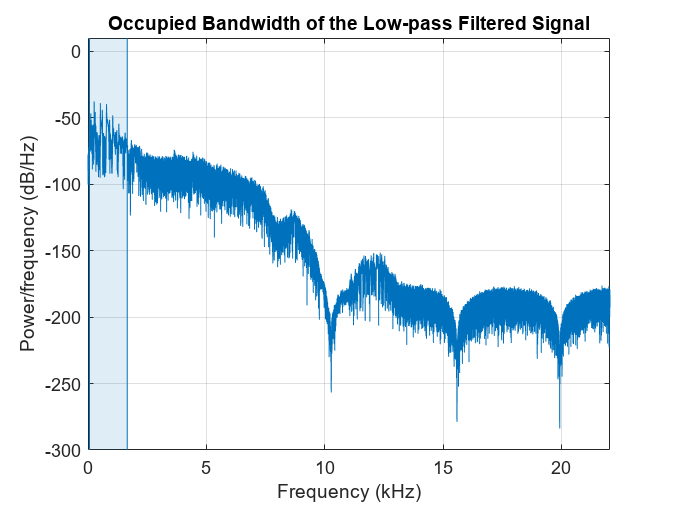

f1 = design(d1, 'window');
Q = filter(f1, y);

% Plot the occupied bandwidth of the low-pass filtered signal
figure;
obw(Q, Fs);
title('Occupied Bandwidth of the Low-pass Filtered Signal');

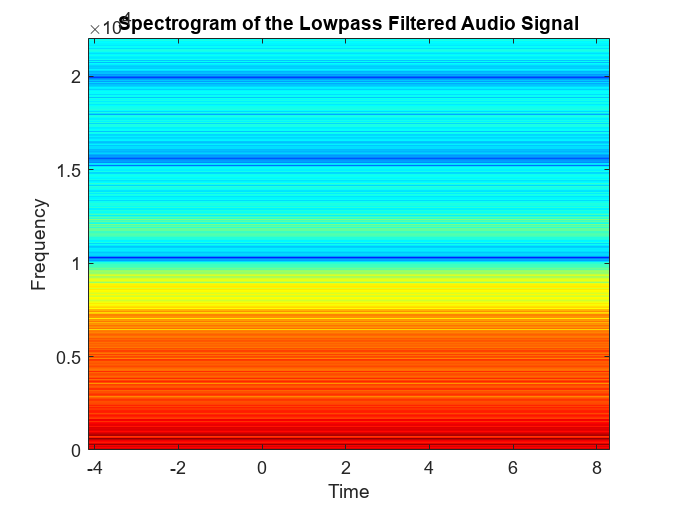


% Spectrogram of the Low-pass filtered signal
figure;
specgram(Q, length(Q), Fs);
title('Spectrogram of the Lowpass Filtered Audio Signal');


% High-pass filter design
d2 = fdesign.highpass('N,Fc', 10, 1200, 48000);
designmethods(d2);

Design Methods for class fdesign.highpass (N,Fc):


window



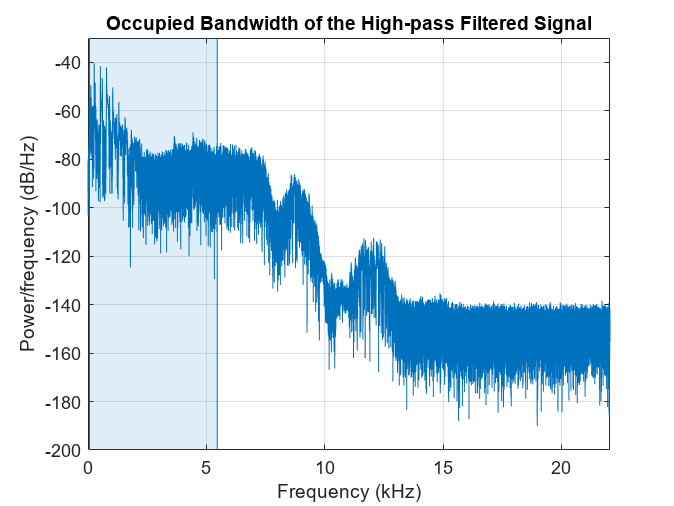

f2 = design(d2, 'window');

% Filter the signal
I = filter(f2, y);

% Plot the occupied bandwidth of the high-pass filtered signal
figure;
obw(I, Fs);
title('Occupied Bandwidth of the High-pass Filtered Signal');

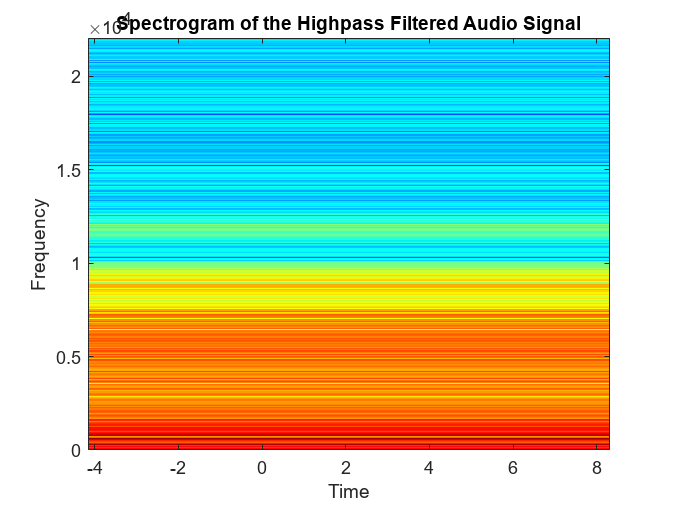


% Spectrogram of the High-pass filtered signal
figure;
specgram(I, length(I), Fs);
title('Spectrogram of the Highpass Filtered Audio Signal');

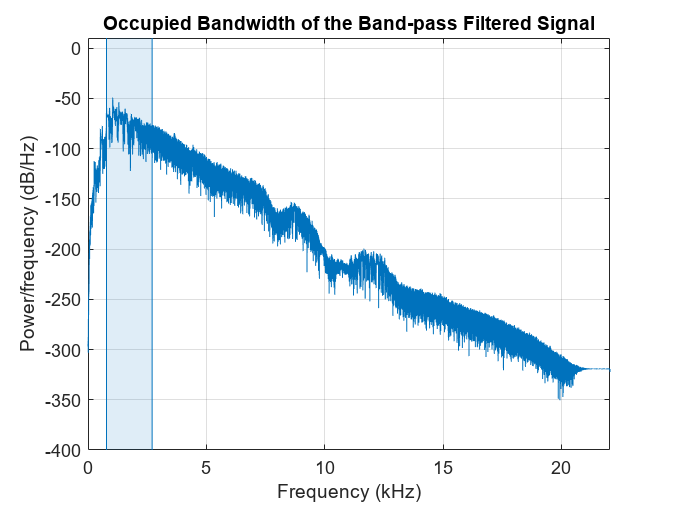


% Bandpass filter design and application
d3 = fdesign.bandpass('N,F3dB1,F3dB2', 10, 1000, 3000, Fs);
f3 = design(d3, 'butter');
bandPassOutput = filter(f3, y);

% Plot the occupied bandwidth of the band-pass filtered signal
figure;
obw(bandPassOutput, Fs);
title('Occupied Bandwidth of the Band-pass Filtered Signal');

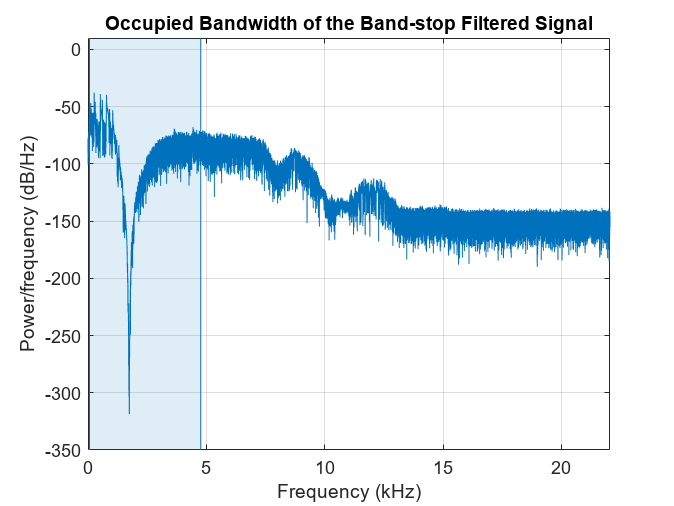


% Bandstop filter design and application
d4 = fdesign.bandstop('N,F3dB1,F3dB2', 10, 1000, 3000, Fs);
f4 = design(d4, 'butter');
bandStopOutput = filter(f4, y);

% Plot the occupied bandwidth of the band-stop filtered signal
figure;
obw(bandStopOutput, Fs);
title('Occupied Bandwidth of the Band-stop Filtered Signal');

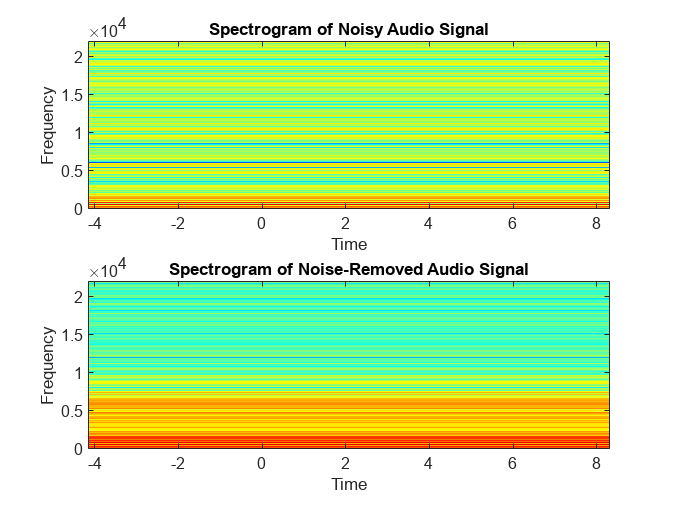


% Add white noise to the signal
noisySignal = awgn(y, 10, 'measured');

% Spectrogram of the noisy audio signal
figure;
subplot(2, 1, 1);
specgram(noisySignal, length(noisySignal), Fs);
title('Spectrogram of Noisy Audio Signal');

% Noise Removal using adaptive filter
mu = 0.001; % step size for the least mean squares (LMS) adaptive filter
L = 64; % length of the adaptive filter
ha = dsp.LMSFilter(L, 'Method', 'Normalized LMS', 'StepSize', mu);
% e will be the filtered signal
[~, e] = ha(noisySignal, y);



% Spectrogram of the noise-removed audio signal
subplot(2, 1, 2);
specgram(e, length(e), Fs);
title('Spectrogram of Noise-Removed Audio Signal');

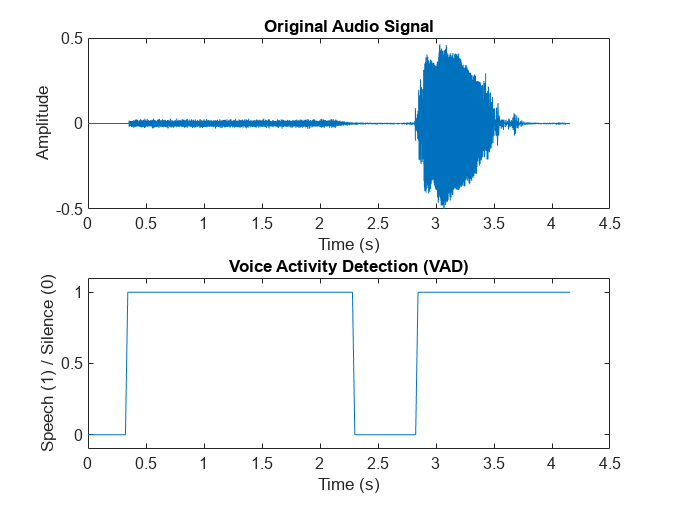


% Set the energy threshold for VAD
energyThreshold = 0.01;

% Calculate the short-term energy of the signal
frameSize = 0.02; % 20 ms frame size
frameSamples = round(frameSize * Fs);
numFrames = floor(length(e) / frameSamples);
energy = zeros(numFrames, 1);

for i = 1:numFrames
    frame = e((i-1)*frameSamples+1:i*frameSamples);
    energy(i) = sum(frame.^2);
end

% Perform Voice Activity Detection (VAD)
isSpeech = energy > energyThreshold;

% Create the time vector for plotting
time = (0:length(e)-1) / Fs;

% Plot the original audio signal
figure;
subplot(2,1,1);
plot(time, y);
title('Original Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Create the time vector for VAD result
timeVAD = linspace(0, length(y)/Fs, length(isSpeech));

% Plot the VAD result
subplot(2,1,2);
plot(timeVAD, isSpeech);
title('Voice Activity Detection (VAD)');
xlabel('Time (s)');
ylabel('Speech (1) / Silence (0)');
ylim([-0.1 1.1]);

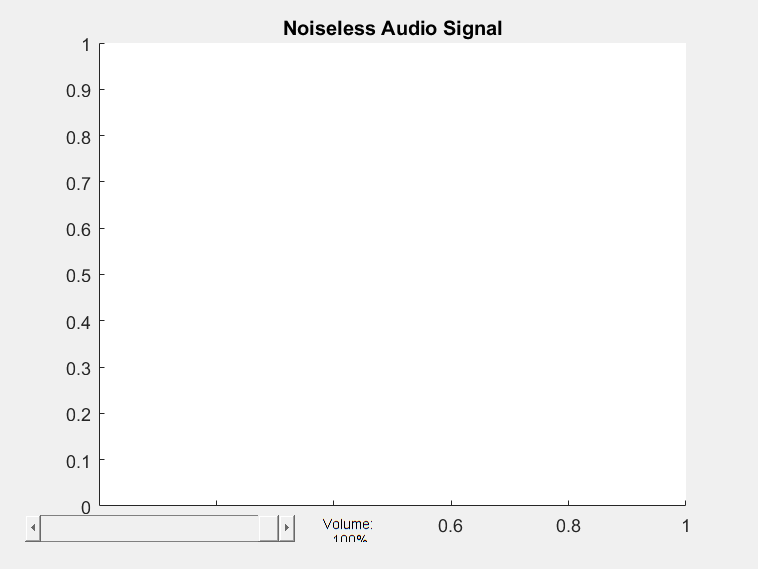


% Create a figure window for volume control
volumeFigure = figure('Name', 'Volume Control');

% Create a slider for volume control
volumeSlider = uicontrol('Style', 'slider', 'Min', 0, 'Max', 1, 'Value', 1, 'Position', [20 20 200 20]);
volumeLabel = uicontrol('Style', 'text', 'String', 'Volume: 100%', 'Position', [230 20 60 20]);

% Callback function for volume control
set(volumeSlider, 'Callback', @(src, event) adjustVolume(y, Fs, src.Value, volumeLabel));

% Play the noisy audio signal
noisySignal = awgn(y, 10, 'measured');
sound(noisySignal, Fs);
title('Noisy Audio Signal');

% Wait for the noisy audio signal to finish playing
pause(length(noisySignal) / Fs);

% Play the noiseless audio signal
sound(y, Fs);
title('Noiseless Audio Signal');


% Calculate the short-term energy of the noise-removed signal
frameSize = 0.02; % 20 ms frame size
frameSamples = round(frameSize * Fs);
numFrames = floor(length(e) / frameSamples); % Change from y to e
energy = zeros(numFrames, 1);

for i = 1:numFrames
    frame = e((i-1)*frameSamples+1:i*frameSamples); % Change from y to e
    energy(i) = sum(frame.^2);
end

% Function to adjust the volume of the audio

function adjustVolume(audio, Fs, volume, volumeLabel)
    sound(audio * volume, Fs);
    volumePercentage = num2str(round(volume * 100));
    volumeLabelText = ['Volume: ' volumePercentage '%'];
    set(volumeLabel, 'String', volumeLabelText);
end

**Reading and Preprocessing the Audio Signal:**

The code begins by clearing the workspace, closing all figures, and clearing the command window. It then reads the audio signal from the file 'GGG.WAV' using the `audioread` function and stores the signal in the variable `y` and the sample rate in `Fs`. The stereo signal is converted to mono by taking the mean of the two channels.

**Spectral Analysis:**

It displays the sample rate of the signal by creating a string `Y` and using the `disp` function. It then plots the spectrogram of the input audio signal using the `specgram` function and creates a subplot.

Power Spectral Density:

The code plots the power spectral density of the signal using the `psd` function and creates another subplot.

Fourier Transform:

We calculated the Fourier Transform of the audio signal using the `fft` function and normalizes it by dividing by the length of the signal. It then calculates the corresponding frequencies and plots the Fourier Transform in a stem plot. Another subplot is created for this graph.

**Bandwidth of the Signal:**

The code plots the bandwidth of the signal by calculating the magnitude spectrum in decibels using `20*log10(abs(FFT))`. It creates a subplot for this graph.

**Filter Design and Application:**

The code designs a low-pass filter using the `fdesign.lowpass` function and applies the filter to the signal using the `filter` function. It then plots the occupied bandwidth of the low-pass filtered signal using the `obw` function.

**Spectrogram of the Low-pass Filtered Signal:**

The code plots the spectrogram of the low-pass filtered audio signal using the `specgram` function and creates a new figure for this.

**High-pass Filter Design and Application:**

The code designs a high-pass filter using the `fdesign.highpass` function and applies the filter to the signal using the `filter` function. It then plots the occupied bandwidth of the high-pass filtered signal using the `obw` function.

**Spectrogram of the High-pass Filtered Signal:**

The code plots the spectrogram of the high-pass filtered audio signal using the `specgram` function and creates a new figure for this.

**Bandpass Filter Design and Application:**

The code designs a bandpass filter using the `fdesign.bandpass` function and applies the filter to the signal using the `filter` function. It then plots the occupied bandwidth of the band-pass filtered signal using the `obw` function.

**Bandstop Filter Design and Application:**

The code designs a bandstop filter using the `fdesign.bandstop` function and applies the filter to the signal using the `filter` function. It then plots the occupied bandwidth of the band-stop filtered signal using the `obw` function.

**Adding White Noise to the Signal:**

The code adds white noise to the original signal using the `awgn` function and stores the noisy signal in the variable `noisySignal`.

**Spectrogram of the Noisy Audio Signal:**

The code plots the spectrogram of the noisy audio signal using the `specgram` function and creates a new figure for this.

**Noise Removal using Adaptive Filter:**

The code implements noise suppression using an adaptive filter. It begins by setting the step size `mu` and the length of the adaptive filter **`L`**. These parameters control the behavior of the adaptive filter.

Next, it creates an instance of the `**dsp.LMSFilter**` object named `**ha**` with the specified length and step size. The filter is set to use the "**Normalized LMS**" method for adaptive filtering.

The `ha` filter is then applied to the noisy signal `noisy

Signal` and the original signal `**y**` using the function call `**[~, e] = ha(noisySignal, y)**`. The `**e**` variable stores the filtered signal.

**Spectrogram of the Noise-Removed Audio Signal:**

The code plots the spectrogram of the noise-removed audio signal `e` using the `specgram` function. It creates a new figure to display the spectrogram.

**Voice Activity Detection (VAD):**

The code sets an energy threshold for VAD (**`energyThreshold`**). It calculates the short-term energy of the noise-removed signal in frames and performs VAD by comparing the energy of each frame to the threshold. The result is stored in the binary variable `isSpeech`.

**Plotting the Original Audio Signal and VAD Result:**

The code creates a figure with two subplots. In the first subplot, it plots the original audio signal (`y`). In the second subplot, it plots the VAD result (`isSpeech`) as a binary plot indicating speech (1) or silence (0).

**Volume Control:**

The code creates a graphical user interface (GUI) for volume control. It creates a figure window and a slider (`volumeSlider`) to adjust the volume level. It also creates a text label (`volumeLabel`) to display the current volume percentage. The `adjustVolume` function is defined to adjust the volume of the audio based on the slider value.

**Playing the Noisy and Noiseless Audio Signals:**

The code plays the noisy audio signal (`noisySignal`) using the `sound` function, and the noiseless audio signal (`y`) is played after a pause.

**Calculation of Short-Term Energy:**

The code calculates the short-term energy of the noise-removed signal in frames, similar to the previous energy calculation. The frames are processed to obtain the energy values.

**Volume Control Callback Function:**

The `adjustVolume` function is defined to adjust the volume of the audio signal based on the slider value. It multiplies the audio signal by the volume factor and updates the volume label.

Overall, the code performs various signal processing and analysis operations on an audio signal, including spectral analysis, filtering, noise removal, VAD, and volume control. The results are visualized using spectrograms, graphs, and plots. The adaptive filter plays a crucial role in reducing noise in the audio signal, and the VAD and volume control enhance the functionality and usability of the system.

## **Results and Analysis**

The project presents the results of each step in the form of figures and plots. The spectrograms of the original signal, noisy signal, and noise-removed signal are displayed to visualize the effects of filtering and noise removal. The VAD result is plotted to show the detected speech and silence regions. Finally, the volume control GUI allows for adjusting the volume level of the audio signal.

Running the provided code will yield several results related to audio signal processing. Here's a discussion of the results obtained from each section of the code:

**Sample Rate:**

   - The code displays the sample rate of the input audio signal, which indicates the number of samples per second. This information helps understand the resolution of the signal and the frequency range it can capture.

**Spectrogram:**

   - The spectrogram of the input audio signal is plotted, showing the time-varying frequency content. It provides insights into the signal's spectral characteristics, such as dominant frequencies and their changes over time.  

**Power Spectral Density and Fourier Transform:**

   - The power spectral density (PSD) of the audio signal is calculated and plotted, revealing the distribution of power across different frequencies.

   - The Fourier Transform of the audio signal is computed, and the resulting frequency spectrum is visualized. This shows the amplitudes of different frequency components in the signal.

**Bandwidth Analysis:**

   - The code plots the graph for the bandwidth of the signal, which provides information about the range of frequencies present in the signal and the distribution of energy.

**Low-pass Filtering:**

   - A low-pass filter is designed and applied to the audio signal to attenuate frequencies above a specified cutoff. The occupied bandwidth of the low-pass filtered signal is calculated and plotted.

**High-pass Filtering:**

   - A high-pass filter is designed and applied to the audio signal to attenuate frequencies below a specified cutoff. The occupied bandwidth of the high-pass filtered signal is calculated and plotted.

**Bandpass and Bandstop Filtering:**

   - Bandpass and bandstop filters are designed and applied to the audio signal. The bandpass filter allows frequencies within a specified range to pass through, while the bandstop filter attenuates frequencies within the same range. The occupied bandwidths of the bandpass and bandstop filtered signals are calculated and plotted.

**Noise Addition and Adaptive Noise Removal:**

   - White noise is added to the original audio signal, and an adaptive filter based on the Least Mean Squares (LMS) algorithm is employed to remove the noise. The spectrogram of the noise-removed audio signal is visualized.

**Voice Activity Detection (VAD):**

   - The energy threshold for Voice Activity Detection (VAD) is set, and the short-term energy of the noise-removed signal is calculated. The VAD result is plotted, indicating speech (1) or silence (0) at different time intervals.

**Volume Control:**

    - A figure window with a volume control slider is created, allowing interactive adjustment of the audio signal's volume. The corresponding volume percentage is displayed.

**Audio Playback:**

    - The noisy audio signal is played, followed by the noiseless audio signal, using the `sound` function. This allows auditory evaluation and comparison of the original and processed signals.

Overall, running this code provides visualizations and analyses of various audio signal processing techniques, including spectral analysis, filtering, noise reduction, voice activity detection, and volume control. These results help understand and improve the quality of the audio signal by applying scientific techniques and algorithms.

## **Conclusion**

The project demonstrates various signal processing and analysis techniques for audio signals. The implemented methods successfully accomplish tasks such as spectral analysis, filtering, noise removal, voice activity detection, and volume control. The results showcase the effectiveness of these techniques in enhancing the quality of audio signals.

## **Future Work**

The project can be extended in several ways. Additional filtering techniques, such as equalization or adaptive filters, can be explored. Advanced noise removal algorithms, such as wavelet denoising or spectral subtraction, can be implemented for improved noise reduction. Moreover, the project can be expanded to include more comprehensive audio analysis, such as pitch detection or audio classification.